# Solving System of Equations for Mesh Analysis 

Arielle Blum

ECEN 2250F21

Solve for the mesh currents IA & IB in terms of only Vs and the resistors. The circuit is shown below:

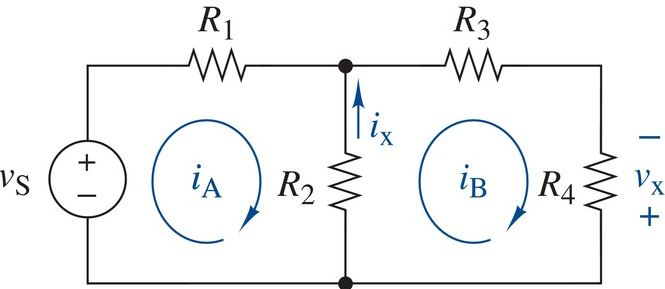

clc

% Define symbolic variables
syms Vs real
syms R1 R2 R3 R4 positive

% Create A Matrix which is the Resistance Matrix (R)
A = [(R1+R2), (-R2); (-R2), (R2 + R3 + R4)]

$$A = \left(\begin{array}{cc} R_{1}+R_{2} & -R_{2}\\ -R_{2} & R_{2}+R_{3}+R_{4} \end{array}\right)$$

% Set up b matrix
b = [Vs; 0]

$$b = \left(\begin{array}{c} \mathrm{Vs}\\ 0 \end{array}\right)$$

% Solve for the mesh currents
x = A\b

$$x = \left(\begin{array}{c} \frac{\mathrm{Vs}\,\left(R_{2}+R_{3}+R_{4}\right)}{R_{1}\,R_{2}+R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}}\\ \frac{R_{2}\,\mathrm{Vs}}{R_{1}\,R_{2}+R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}} \end{array}\right)$$

% Assign to mesh currents IA and IB
IA = x(1)

$$IA = \frac{\mathrm{Vs}\,\left(R_{2}+R_{3}+R_{4}\right)}{R_{1}\,R_{2}+R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}}$$

IB = x(2)

$$IB = \frac{R_{2}\,\mathrm{Vs}}{R_{1}\,R_{2}+R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}}$$

% Given Vx = -IB*R4 VA & Ix = -(IA-IB)
Vx = simplify(-IB*R4)

$$Vx = -\frac{R_{2}\,R_{4}\,\mathrm{Vs}}{R_{1}\,R_{2}+R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}}$$

Ix = simplify(-(IA-IB))

$$Ix = -\frac{\mathrm{Vs}\,\left(R_{3}+R_{4}\right)}{R_{1}\,R_{2}+R_{1}\,R_{3}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{2}\,R_{4}}$$